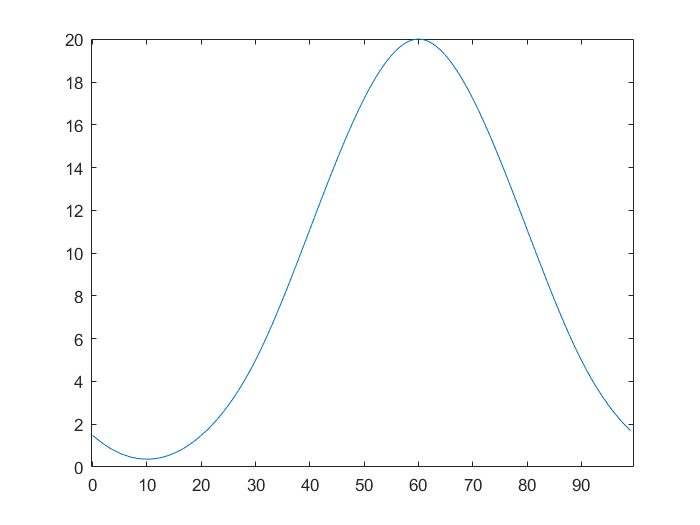

clear all;
close all;
clc;

% DFT for the triangle.
% Triangle signal
x = 0:99;
y = (30 - abs(x-30)) / 30;
y(61:100) = 0;
triangle_fft = fft(y);
% triangle_fft_mag = abs(triangle_fft);

product_of_triangle_itself = triangle_fft .* triangle_fft;
recovered_signal = ifft(product_of_triangle_itself);
x = 0:99;
plot(x, recovered_signal);